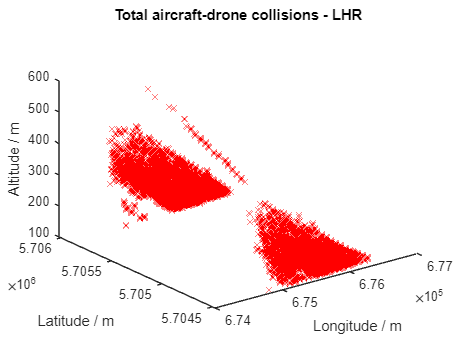

clear
clc
close all

distance_from_airport = "1.0";
airport = "LHR";
drone_model = "Mini_2"; % Either Mavic_3 or Mini_2
depart_or_arrive = 0; % Depart = 0; Arrival = 1

[run_number,longitude,latitude,altitude,drone_speed,aircraft_index,aircraft_speed,time] = multipleSims(distance_from_airport,airport,drone_model,depart_or_arrive);

% Total number of Monte Carlo runs per test case
total_MC_runs = longitude(end-2);

local_collisions = zeros(1,total_MC_runs);
sim_index = zeros(1,total_MC_runs);

idx = 1;

for i = 2:length(run_number)
    if run_number(i) ~= run_number(i-1)
        if isnan(latitude(i-1))
            break
        end
        sim_index(idx) = i-1;
        local_collisions(idx) = latitude(i-1);
        idx = idx + 1;
    end
end

total_collisions = sum(local_collisions);
total_simulations = longitude(end-3);
average_collisions = total_collisions / total_MC_runs;
average_col_percent = total_collisions / total_simulations;

%%%%%%%%%%%%%%%%%%%%%%% Identifying Clusters of collisions %%%%%%%%%%%%%%%%%%%%%

figure()
plot3(longitude(1:sim_index(1)),latitude(1:sim_index(1)),altitude(1:sim_index(1)), 'rx')
hold on
for i = 2:length(sim_index)
    plot3(longitude(sim_index(i-1)+1:sim_index(i)),latitude(sim_index(i-1)+1:sim_index(i)),altitude(sim_index(i-1)+1:sim_index(i)), 'rx')
end
title("Total aircraft-drone collisions - " + airport)
xlabel("Longitude / m")
ylabel("Latitude / m")
zlabel("Altitude / m")
hold off

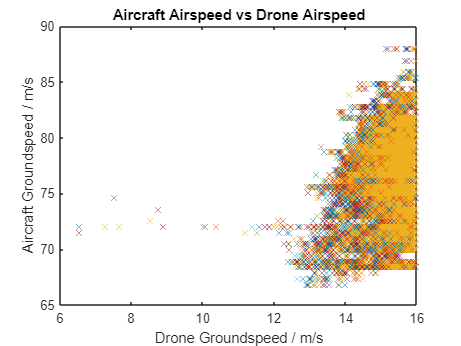


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Plotting Airspeed %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure()
plot(drone_speed(1:sim_index(1)),aircraft_speed(1:sim_index(1)),'x')
hold on
for i = 2:length(sim_index)
    plot(drone_speed(sim_index(i-1)+1:sim_index(i)),aircraft_speed(sim_index(i-1)+1:sim_index(i)), 'x')
end
title("Aircraft Airspeed vs Drone Airspeed")
xlabel("Drone Groundspeed / m/s")
ylabel("Aircraft Groundspeed / m/s")
hold off

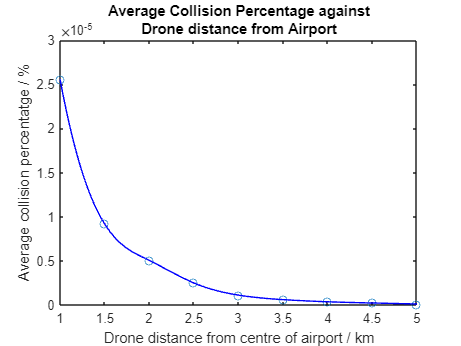

distance_from_airport = (1.0:0.5:5.0);
all_avg_col_percent = zeros(1,length(distance_from_airport));
all_avg_time = zeros(1,length(distance_from_airport));

for i = 1:length(distance_from_airport)
    distance = sprintf('%0.1f',distance_from_airport(i));
    [run_number,longitude,latitude,altitude,drone_speed,aircraft_index,aircraft_speed,time] = multipleSims(distance,airport,drone_model,depart_or_arrive);
    
    % Total number of Monte Carlo runs per test case
    total_MC_runs = longitude(end-2);
    total_collisions = longitude(end-4);
    total_simulations = longitude(end-3);
    average_collisions = total_collisions / total_MC_runs;
    all_avg_col_percent(i) = total_collisions / total_simulations;
    time = time(~isnan(time));
    all_avg_time(i) = tsnansum(time)/length(time);
end

discretised_distance = linspace(distance_from_airport(1),distance_from_airport(end),1000);

avg_col_spline = spline(distance_from_airport,all_avg_col_percent,discretised_distance);
figure()
plot(distance_from_airport,all_avg_col_percent,'o')
hold on
plot(discretised_distance,avg_col_spline,'-b');
title({"Average Collision Percentage against", "Drone distance from Airport"})
xlabel("Drone distance from centre of airport / km")    
ylabel("Average collision percentatge / %")
hold off

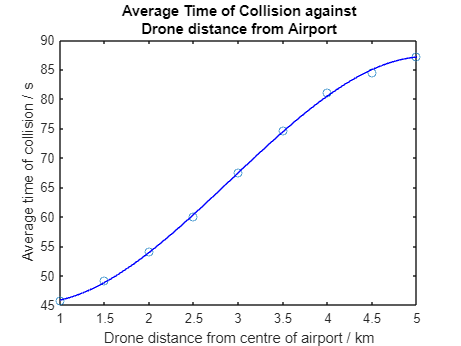


test = polyfit(distance_from_airport,all_avg_time,3);
test1 = polyval(test,discretised_distance);
avg_time_spline = spline(distance_from_airport,all_avg_time,discretised_distance);
figure()
plot(distance_from_airport,all_avg_time,'o')
hold on
plot(discretised_distance,test1,'-b');
title({"Average Time of Collision against" , "Drone distance from Airport"})
xlabel("Drone distance from centre of airport / km")
ylabel("Average time of collision / s")
hold off

function [run_number,longitude,latitude,altitude,drone_speed,aircraft_index,aircraft_speed,time] = multipleSims(distance_from_airport,airport,drone_model,depart_or_arrive)

if depart_or_arrive == 0
    d_a = "Depart";
elseif depart_or_arrive == 1
    d_a = "Arrival";
end

drone_data = table2struct(readtable(airport + "/Drone_Collisions_" + distance_from_airport + "_km/" + drone_model + "/" + d_a + "/Batch_Testing/Average_Collisions.csv",'Delimiter',','));   
run_number = str2double(string({drone_data.run_number}));
longitude = str2double(string({drone_data.longitude}));
latitude = str2double(string({drone_data.latitude}));
altitude = str2double(string({drone_data.altitude}));
drone_speed = str2double(string({drone_data.drone_speed}));
aircraft_index = str2double(string({drone_data.aircraft_index}));
aircraft_speed = str2double(string({drone_data.aircraft_speed}));
time = str2double(string({drone_data.time}));

end